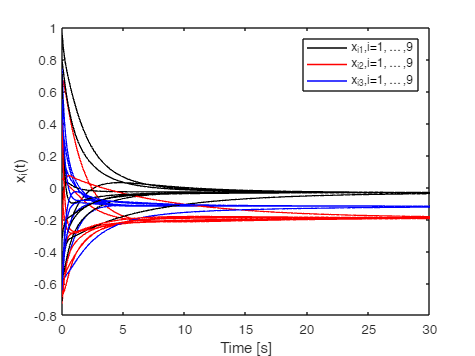

global L
n = 9;
m = 14;
d = 3;
size = 1;
rng(5);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
A12 = [1 sqrt(3)/2 0; sqrt(3)/2 1 0; 0 0 0];
A13 = [0  0 0; 0 1 0; 0 0 1];
A23 = [2  1 0; 1 1 0; 0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0; 0 0 0; 0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
[V,D] = eig(L,'vector');
x0 = [];                        % the agents are initially located on the unit sphere
for i = 1:9
    r = 2*(rand(3,1)-0.5);
    x0 = [x0;r/norm(r)];        
end
[t,x] = ode45(@consensus,[0:0.1:30],x0);
x = x';
e = zeros(1,length(t));
for i=1:length(t)
    e(1,i) = norm(L*x(:,i),2);
end
% plotting the states versus time
figure
hold on;
for i=1:9
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1},i=1,\ldots,9','x_{i2},i=1,\ldots,9','x_{i3},i=1,\ldots,9'},"NumColumns",1)

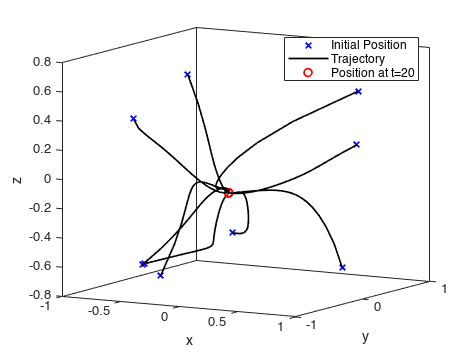


figure
hold on;
for i=1:9
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at t=20'},"NumColumns",1)
view(30,10)

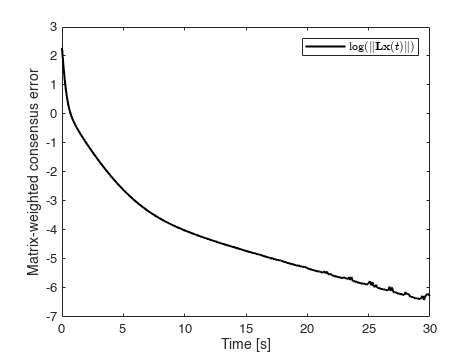


figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

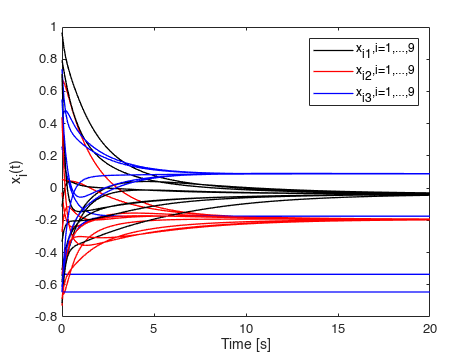


% Graph G2
A13 = [0  0 0; 0 1 0; 0 0 0];
A24 = A13; A34 = A13; A46 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;


[t,x] = ode45(@consensus,[0:0.1:20],x0);
x = x';
e = zeros(1,length(t));
for i=1:length(t)
    e(1,i) = norm(L*x(:,i),2);
end
% plotting the states versus time
figure
hold on;
for i=1:9
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1},i=1,\ldots,9','x_{i2},i=1,\ldots,9','x_{i3},i=1,\ldots,9'},"NumColumns",1)

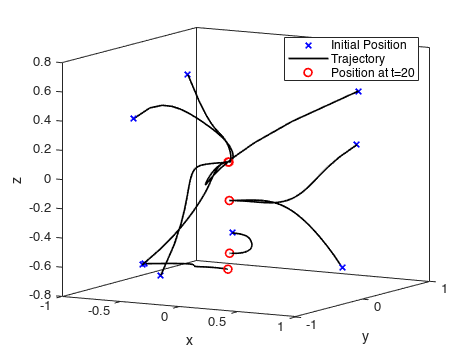


figure
hold on;
for i=1:9
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at t=20'},"NumColumns",1)
view(30,10)

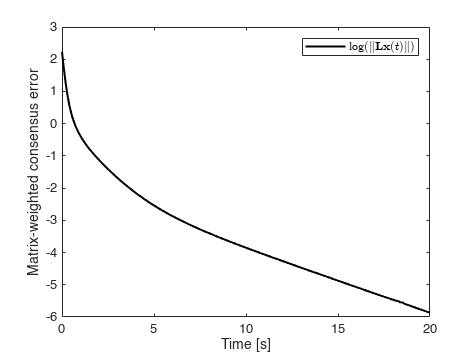

figure
figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

function dx = consensus(t,x)
    global L
    dx = -L*x;
end